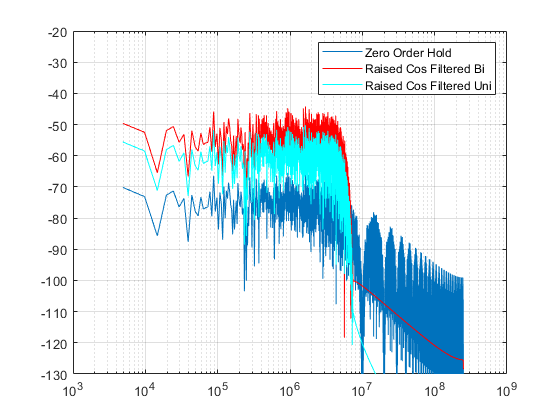

% Signal Params
% Data Params
numberOfBits = 2048;
bits = randi([0, 1],[1, numberOfBits]);
bitRate = 10e6;
A = 5;

% Sampling Params
samplesPerBit = 50;
Fs = bitRate*samplesPerBit;
Ts = 1/Fs;
L = samplesPerBit*numberOfBits;
time = Ts*(0:L-1);
bitTime = 1/bitRate;


% Raised Cos Pulse Shape
rollOffFactor = 0.5;
p = @(t, dataRate, rollOff) ...
    cos(pi*dataRate*rollOff*t)...
    .*sinc(dataRate*t)...
    ./(1 - 4*rollOff^2*dataRate^2*t.^2) * dataRate;
% Rect Pulse Shape
rect = @(t, T) ...
    (ceil(heaviside(t)) - ceil(heaviside(t - T*ones(size(t)))));


% Generate Upsampled Bits
zoh = ones([1 samplesPerBit]);
bitsUpsampled = upsample(bits, samplesPerBit);
bitsZoh = convfft(bitsUpsampled, zoh);
bitsZoh = bitsZoh(1:L)';
bitsZoh(bitsZoh > 0.5) = 1;
bitsZoh(bitsZoh <= 0.5) = 0;

% Raised Cos Filtering of Bits
% rcFilter = p(time, bitRate, rollOffFactor);
% rcFilter(isinf(rcFilter)) = NaN;
% rcFilter = fillmissing(rcFilter, 'linear');
% rcFilter = rcFilter/max(rcFilter);
% 
% numberOfTaps = 151;
% t = (-numberOfTaps/2:numberOfTaps/2-1)*Ts;
% h = 1/Ts.*sinc(t/Ts) .* cos(pi*rollOffFactor*t/Ts) ./ (1 - (2*rollOffFactor*t/Ts).^2);
% stem(h)
% 
% 
% % Create Bipolar and Unipolar Data with Pulse Shaping
xBi = 2*A*bitsZoh - A;
xUni = A*bitsZoh;
% xBiShaped = convfft(xBi, rcFilter);
% xUniShaped = convfft(xUni, rcFilter);
% 

xBiShaped = zeros(size(time));
xUniShaped = zeros(size(time));
for k = 1:numberOfBits
        xBiShaped = xBiShaped + A*(2*bits(k) - 1)*p(time - k*bitTime*ones(size(time)), bitRate, rollOffFactor);
        if bits(k) == 1
            xUniShaped = xUniShaped + A*p(time - k*bitTime*ones(size(time)), bitRate, rollOffFactor);
        end
end
xBiShaped = xBiShaped/sqrt(var(xBiShaped))*sqrt(var(xBi));
xUniShaped = xUniShaped/sqrt(var(xUniShaped))*sqrt(var(xUni));

% Rect Filtering
% xBiShaped = xBi;
% xUniShaped = xUni;


% Shift Shaped Vectors to corect for length mismatch (for RC Filtering)
% [RxBi, tau1] = xcorr(xBi, xBiShaped);
% [RxUni, tau2] = xcorr(xUni, xUniShaped);
% 
% idx1 = find(RxBi == max(RxBi));
% idx1 = tau1(idx1);
% 
% idx2 = find(RxUni == max(RxUni));
% idx2 = tau1(idx2);
% 
% 
% xBiShaped = xBiShaped(-idx1:end);
% xBiShaped = xBiShaped/sqrt(var(xBiShaped))*sqrt(var(xBi));
% 
% xUniShaped = xUniShaped(-idx2:end);
% xUniShaped = xUniShaped/sqrt(var(xUniShaped))*sqrt(var(xUni));
% 
% assert(length(xBiShaped) == length(xUniShaped))
% time = time(1:length(xBiShaped));
% 

% Check PSD of Data
[Sb, f1] = periodogram(bitsZoh,rectwin(length(bitsZoh)),length(bitsZoh), Fs, 'onesided');
[Sxb, f2] = periodogram(xBiShaped,rectwin(length(xBiShaped)),length(xBiShaped), Fs, 'onesided');
[Sxu, f3] = periodogram(xUniShaped,rectwin(length(xUniShaped)),length(xUniShaped), Fs, 'onesided');

% semilogx(f1, 10*log10(Sb))
% hold on
% semilogx(f2, 10*log10(Sxb), 'r')
% semilogx(f3, 10*log10(Sxu), 'c')
% grid on
% legend('Zero Order Hold', 'Raised Cos Filtered Bi', 'Raised Cos Filtered Uni')
% ylim([-130, -20])


% Generate Noise with Power 1
% SNRdB = 0;
% variance = 1/(Ts*(10^(SNRdB/10)));
snrPerBit = 10;
snrPerBit = 10.^(snrPerBit/10);
variance = (A^2*samplesPerBit)/(2*snrPerBit);
noise = sqrt(variance)*randn(size(time));
var(noise)

ans = 0


% Create Rx Sequence
rxSequenceBi = xBiShaped + noise;
rxSequenceUni = xUniShaped + noise/sqrt(2);


% Generate Matched Filter Impulse Response
% Filter is matched to Raised Cos Pulse Shape
g = @(t, dataRate, rollOff) ...
    cos(pi*dataRate*rollOff*t).*sinc(dataRate*t)...
    ./(1 - 4*rollOff^2*dataRate^2*t.^2);
h = g(bitTime - time + max(time)/2, bitRate, rollOffFactor);
%rcFilter = p(time - max(time)/2, bitRate, rollOffFactor);
% For Rect Matched Filters
% hRect = rect(bitTime*ones(size(time)) - time, bitTime);



% Clean up filter impulse response
h(isinf(h)) = NaN;
h = fillmissing(h, 'linear');
% hRect(isinf(hRect)) = NaN;
% hRect = fillmissing(hRect, 'linear');


% Apply Matched Filter to Rx Sequence
yBi = convfft(rxSequenceBi, h);
yUni = convfft(rxSequenceUni, h);

% For Rect Shape
% yBi = convfft(rxSequenceBi, hRect);
% yUni = convfft(rxSequenceUni, hRect);

% Shift Filtered Vectors to corect for length mismatch
% Normalize to unit variance
[RyBi, tau3] = xcorr(rxSequenceBi, yBi);
[RyUni, tau4] = xcorr(rxSequenceUni, yUni);

idx3 = find(RyBi == max(RyBi));
idx3 = tau3(idx3);

idx4 = find(RyUni == max(RyUni));
idx4 = tau4(idx4);

yBi = yBi(-idx3:L-idx3-1)';
yBi = yBi/sqrt(var(yBi));

yUni = yUni(-idx4:L-idx4-1)';
yUni = yUni/sqrt(var(yUni));

assert(length(yUni) == length(yBi))
% time = time(1:length(yBi));

% Decimate Rx Signal to contain 1 sample per bit
mUni = zeros([1, numberOfBits]);
mBi = zeros([1, numberOfBits]);

for k = 1:numberOfBits
    startIdx = (k-1)*samplesPerBit+1;
    endIdx = k*samplesPerBit;
    mBi(k) = yBi(endIdx);
    mUni(k) = yUni(endIdx);
end


% Threshold Decimated Rx Signal to Recover Bits
mBi = sign(mBi);
mBi = 0.5*mBi + 0.5;

nbins = 200;
[N,edges] = histcounts(mUni,nbins);
Nsort = sort(N);
peak1 = Nsort(end);
peak2 = Nsort(end-1);
idx1 = find(N == peak1);

idx1 = 151

idx2 = min(find(N == peak2));

idx2 =     24    48


thres1 = edges(idx1);

thres1 = 1.8755

thres2 = edges(idx2);

thres2 =     0.0251    0.3748


mUni = sign(mUni - (thres1 + thres2)/2);

Matrix dimensions must agree.

mUni = 0.5*mUni + 0.5;


% 
% % Check for Sample Delay
% [RbmBi, tau5] = xcorr(mBi, bits, 'biased');
% idx5 = find(RbmBi == max(RbmBi));
% idx5 = tau5(idx5);
% idx5 = abs(idx5);
% 
% [RbmUni, tau6] = xcorr(mUni, bits, 'biased');
% idx6 = find(RbmUni == max(RbmUni));
% idx6 = tau6(idx6);
% idx6 = abs(idx6);
% % plot(tau, RbmBi)
% % grid on
% 
% mBiShift = mBi(idx5+1:(length(mBi)+idx5-1));
% mBiShift = mBiShift/2 + 0.5;

% Adjust for Sample Delay Caused by Matched Filter
% mBiShift = mBi(3:end);
% mBiShift = mBiShift/2 + 0.5;

% mUniShift = mUni(3:end);
% mUniShift = mUniShift/2 + 0.5;
% mUniShift = mUni(idx6+1:(length(mUni)+idx6-1));
% mUniShift = mUniShift/2 + 0.5;
% 
% bitsShift = bits(1:end-1);

% Check for 0 Shift between Bits and Rx Signal
% [RbmBiShift, tauShift] = xcorr(mBiShift, bitsShift, 'biased');
% plot(tauShift, RbmBiShift)
% grid on

% Calculate Bit Error Rate
bitCheckBi = xor(bits, mBi);
bitErrorRateBi = sum(bitCheckBi)/numberOfBits

bitCheckUni = xor(bits, mUni);
bitErrorRateUni = sum(bitCheckUni)/numberOfBits

% Theo Bit Error Rate
% P(Err) = Q(sqrt(Eb/N0))
% Q(x) = 0.5*efrc(x/sqrt(2))

singleBit = A*p(time - 10*bitTime, bitRate, rollOffFactor);
singleBit(isinf(singleBit)) = NaN;
singleBit = fillmissing(singleBit, 'linear');
singleBit = singleBit/max(singleBit);
bitEnergy = trapz(time,singleBit.^2);

noisePower = var(noise);
N0 = noisePower/(Fs/2);

bitErrorRateTheo = 0.5*erfc(sqrt(2*bitEnergy/N0)/sqrt(2))*100

% SNR
SNR = var(xBiShaped)/var(noise);
SNR = 10*log10(SNR)

% Plotting
timeSampleLength = 100;

subplot(3,1,1)
plot(time/bitTime, xUniShaped+noise, 'LineWidth', 2)
hold on
plot(time/bitTime, xBiShaped+noise, 'LineWidth', 2)
grid on
xlabel('Bit Time (s/s)')
ylabel('Tx Bits')
% xticks(1:numberOfBits)
legend('Unipolar', 'Bipolar')
title('Pulses Before Matched Filter')
xlim([numberOfBits/2, numberOfBits/2+timeSampleLength])

subplot(3,1,2)
plot(Ts*(0:length(yUni)-1)/bitTime, yUni, 'LineWidth', 2)
hold on
plot(Ts*(0:length(yBi)-1)/bitTime, yBi, 'LineWidth', 2)
plot(time/bitTime, bitsZoh, 'LineWidth', 2, 'LineStyle',"-.")
grid on
xlabel('Bit Time (s/s)')
ylabel('Tx Bits')
legend('Unipolar', 'Bipolar', 'Tx Bits')
% xticks(1:numberOfBits)
% xlim([1, numberOfBits])
xlim([numberOfBits/2, numberOfBits/2+timeSampleLength])
title('Pulses After Matched Filter')

subplot(3,1,3)
stem(mBiShift-bitsShift)
hold on
stem(mUniShift-bitsShift)
% stem(bitsShift)
xlim([numberOfBits/2, numberOfBits/2+timeSampleLength])
grid on
xlabel('Bit Time (s/s)')
ylabel('Tx Bits')
legend('Bipolar Bit Errors', 'Unipolar Bit Errors')
title('Bit Errors')